# Preprocessing of Neuropixels recordings in the flight room

- Recording date: 2/7/2024

- Recording method: untethered recording in the flight room.

- Experiment setup: multiple bats (n=10) were flew in the flight room simultaneously. Two bats (14633 and 14662) were recorded for their neural activity.

- Target region of ephys recording: 14633 and 14662 was implanted with two probes respectively. For 14633, the probe 1 was targetting the dorsal/ventral hippocampus and the probe 2 was targetting the mEC. For 14662, the probe 1 was targetting the hippocampus and the mEC and the probe 2 was targetting the dorsal and ventral hippocampus.

- Feeder: feeder 1 and 2 was activated with a banana smoothie syringe.

## Recording information (Edit here)

rec_date = '240209'; % recording date
rec_type = 'untethered'; % recording type
exp_type = 'flight'; % experiment type
data_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240209_2'; % parent directory for all recordings
cd(data_dir)

% Bat subjects
bname = {"14447","11827","29924","14406","14561","14662","14531","71050","9776"}; % in order of serial number list
bname_ephys = {'14662'}; % ephys bat

% reward
reward_list = {"banana","pear","grape","melon"};
reward_session = [1,1,0,0];
save('exp_info.mat','rec_date','rec_type','exp_type','bname','bname_ephys','reward_list','reward_session')


### Directory to ouput the results

% output directory
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing of Neuropixels data

### Extracting LFP, spikeband, and other data types    

trodes_path = 'C:\Users\Tatsumi\Documents\Trodes\Trodes_2-5-0_Windows64'; % trodes 2.5.0
exportAllTrodesRecordingsAllBats(data_dir,trodes_path,'isTethered',0); % extract LFP, spikeband, kilosort dat, etc. from the raw data for all bats

Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633\20240207_103632_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633" -interp 0
Using the following workspace file:  "20240207_103632_merged.trodesconf"
Exporting data...
1.092%2.183%3.275%4.366%5.458%6.549%A gap of 513 packets occured in the file. Last timestamp:  15806085 (Clock is:  "00:08:46" )
A gap of 514 packets occured in the file. Last timestamp:  15811550 (Clock is:  "00:08:47" )
A gap of 514 packets occured in the file. Last timestamp:  15817016 (Clock is:  "00:08:47" )
A gap of 515 packets occured in the file.

chanmap_file = struct with fields:
       name: '20240207_103632_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633\20240207_103632_merged.kilosort'
       date: '10-Feb-2024 02:31:18'
      bytes: 5253
      isdir: 0
    datenum: 7.3929e+05


Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662\20240207_103632_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662" -interp 0
Using the following workspace file:  "20240207_103632_merged.trodesconf"
Exporting data...
A gap of 282 packets occured in the file. Last timestamp:  5216867 (Clock is:  "00:02:53" )
1.085%2.17%3.255%A gap of 4 packets occured in the file. Last timestamp:  10306457 (Clock is:  "00:05:43" )
A gap of 169 packets occured in the file. Last timestamp:  10708103 (Clock is:  "00:05:56" )
4.339%A gap of 45 packets occured in the file. Last timestamp: 

chanmap_file = struct with fields:
       name: '20240207_103632_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662\20240207_103632_merged.kilosort'
       date: '10-Feb-2024 04:36:02'
      bytes: 2757
      isdir: 0
    datenum: 7.3929e+05


chanmap_file = struct with fields:
       name: '20240207_103632_merged.channelmap_probe2.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662\20240207_103632_merged.kilosort'
       date: '10-Feb-2024 04:36:02'
      bytes: 3333
      isdir: 0
    datenum: 7.3929e+05


### Run kilosort

% 14662
path_to_rec_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240209_2\ephys\20240209_154525.rec\14662'
probeNum = 1;
numChannels = 384;
runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)

## Preprocessing of cdp data

### Data directory

time 565.56, Shifted up/down 591 batches. 
0.58 sec, 1 batches, 10000 spikes 
50.68 sec, 101 batches, 1010000 spikes 
100.47 sec, 201 batches, 2010000 spikes 
150.14 sec, 301 batches, 3010000 spikes 
199.76 sec, 401 batches, 4010000 spikes 
249.80 sec, 501 batches, 5010000 spikes 
294.53 sec, 591 batches, 5902342 spikes 
time 0.00, GROUP 1/384, units 0 
time 1.65, GROUP 6/384, units 12 
time 4.79, GROUP 11/384, units 28 
time 7.08, GROUP 16/384, units 42 
time 8.78, GROUP 21/384, units 52 
time 10.60, GROUP 26/384, units 62 
time 12.89, GROUP 31/384, units 74 
time 14.76, GROUP 36/384, units 85 
time 16.80, GROUP 41/384, units 96 
time 19.45, GROUP 46/384, units 109 
time 23.13, GROUP 51/384, units 127 
time 29.31, GROUP 56/384, units 151 
time 33.25, GROUP 61/384, units 167 
time 35.85, GROUP 66/384, units 179 
time 38.82, GROUP 71/384, units 192 
time 42.45, GROUP 76/384, units 208 
time 50.52, GROUP 81/384, units 242 
time 52.57, GROUP 86/384, units 254 
time 54.87, GROUP 91/384, un

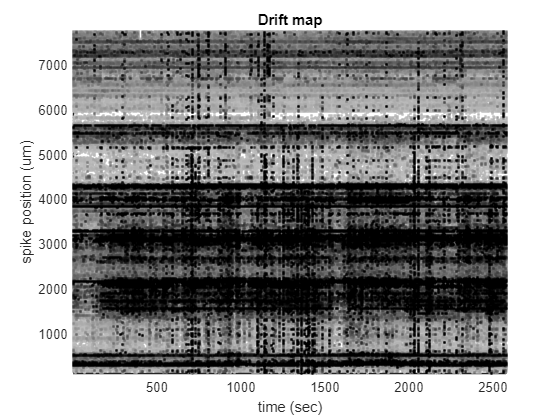

273.53 sec, 101 / 591 batches, 1090 units, nspks: 1355440, mu: 8.6016, nst0: 9737 
307.94 sec, 201 / 591 batches, 1090 units, nspks: 2719258, mu: 8.6016, nst0: 12660 
342.99 sec, 301 / 591 batches, 1090 units, nspks: 4075293, mu: 8.6016, nst0: 13647 
377.78 sec, 401 / 591 batches, 1090 units, nspks: 5442452, mu: 8.6016, nst0: 10444 
410.64 sec, 501 / 591 batches, 1090 units, nspks: 6626880, mu: 8.6016, nst0: 12864 
Elapsed time is 441.541544 seconds.
time 0.00, GROUP 1/384, units 0 
time 0.01, GROUP 6/384, units 0 
time 0.02, GROUP 11/384, units 0 
time 0.02, GROUP 16/384, units 0 
time 0.03, GROUP 21/384, units 0 
time 0.03, GROUP 26/384, units 0 
time 0.04, GROUP 31/384, units 0 
time 0.04, GROUP 36/384, units 0 
time 0.05, GROUP 41/384, units 0 
time 0.05, GROUP 46/384, units 0 
time 0.06, GROUP 51/384, units 0 
time 0.06, GROUP 56/384, units 0 
time 0.06, GROUP 61/384, units 0 
time 0.07, GROUP 66/384, units 0 
time 0.07, GROUP 71/384, units 0 
time 0.08, GROUP 76/384, units 0 
tim

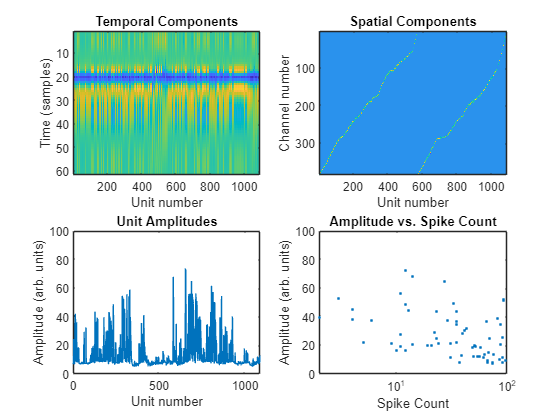

ans = 192

initialized spike counts
merged 222 into 225 
merged 569 into 565 
merged 600 into 599 
merged 150 into 154 
merged 562 into 565 
merged 229 into 234 
merged 568 into 561 
merged 478 into 470 
merged 561 into 567 
merged 161 into 163 
merged 473 into 475 
merged 261 into 264 
merged 61 into 56 
merged 30 into 27 
merged 258 into 264 
merged 196 into 192 
merged 558 into 566 
merged 276 into 275 
merged 292 into 291 
merged 251 into 253 
merged 200 into 207 
merged 270 into 272 
merged 540 into 545 


ans = 172

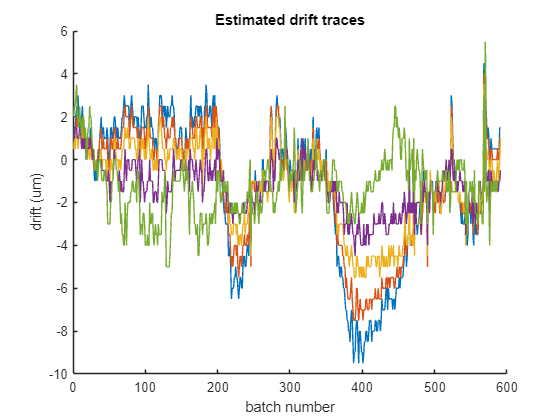

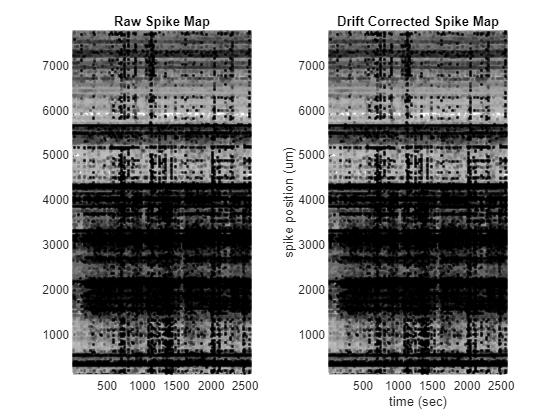

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [384×1 double]
                 yc: [384×1 double]
            xcoords: [384×1 double]
            ycoords: [384×1 double]
               Wrot: [384×384 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×384 gpuArray]
               dist: [10×3452 single]
              iorig: [591×1 double]
             dshift: [591×5 double]
                st0: [4464209×6 double]
                  F: [1534×20×591 double]
                 F0: [1534×20 gpuArray]
                F0m: [1534×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×3452 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 0 8 

% cdp
cdp_dir = dir(fullfile(data_dir,'cdp','*cdp*.txt')); cdp_path = fullfile(cdp_dir.folder,cdp_dir.name);

% serial number
serial_dir = dir(fullfile(data_dir,'*Serial_numbers*')); serial_path = fullfile(serial_dir.folder,serial_dir.name);
% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));

% experiment info
load('exp_info.mat')
n_session = size(reward_session,1);
reward_summary = cell(n_session,4);
for i = 1:n_session
    for fd = 1:4
        fl = reward_session(i,fd);
        if fl ~= 0
            reward_summary{i,fd} = reward_list{fl};
        end
    end
end
reward_summary

### Preprocess the cdp data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data

reward_summary = 1×4 cell array
    {'banana'}    {'banana'}    {0×0 double}    {0×0 double}


                 Fs: 100
             tag_SN: [10×1 double]
            sync_SN: 17040920
               sync: 1
      sync_duration: 28.5297
       sync_samples: 171171
       tag_duration: [28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5306 28.5304]
        tag_samples: [170306 170252 170354 170276 170291 154435 170314 162235 170214 170279]
    tag_ac_duration: [28.5305 28.5304 28.5303 28.5304 28.5304 28.5304 28.5305 28.5305 28.5304 28.5304]
     tag_ac_samples: [170289 170309 172164 171475 172088 155443 172799 163493 172589 171176]
               tags: 10

All TTLs were detected, alignment OK
Sync: Fs (network time VS interpolated): 100Hz VS 98.12 Hz
Pos Tag1: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag2: Fs (network time VS interpolated): 99.46 Hz VS 97.6 Hz


Pos Tag3: Fs (network time VS interpolated): 99.52 Hz VS 97.65 Hz


Pos Tag4: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Pos Tag5: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz


Pos Tag6: Fs (network time VS interpolated): 90.22 Hz VS 88.53 Hz


Pos Tag7: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag8: Fs (network time VS interpolated): 94.77 Hz VS 93 Hz


Pos Tag9: Fs (network time VS interpolated): 99.43 Hz VS 97.57 Hz


Pos Tag10: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Acc Tag1: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz
Acc Tag2: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz
Acc Tag3: Fs (network time VS interpolated): 100.6 Hz VS 98.69 Hz
Acc Tag4: Fs (network time VS interpolated): 100.2 Hz VS 98.3 Hz
Acc Tag5: Fs (network time VS interpolated): 100.5 Hz VS 98.65 Hz
Acc Tag6: Fs (network time VS interpolated): 90.8 Hz VS 89.11 Hz
Acc Tag7: Fs (network time VS interpolated): 100.9 Hz VS 99.06 Hz
Acc Tag8: Fs (network time VS interpolated): 95.51 Hz VS 93.72 Hz
Acc Tag9: Fs (network time VS interpolated): 100.8 Hz VS 98.94 Hz
Acc Tag10: Fs (network time VS interpolated): 100 Hz VS 98.13 Hz


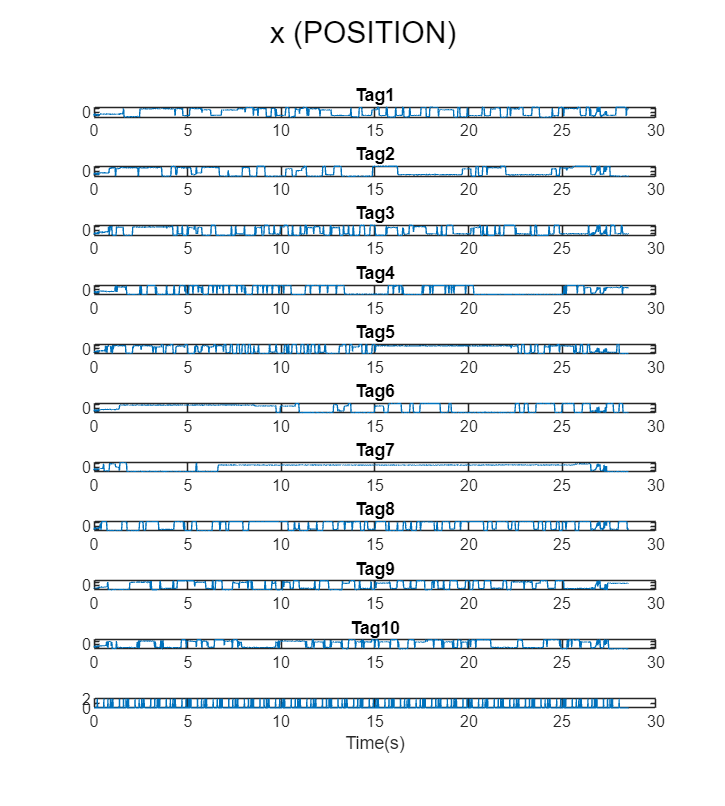

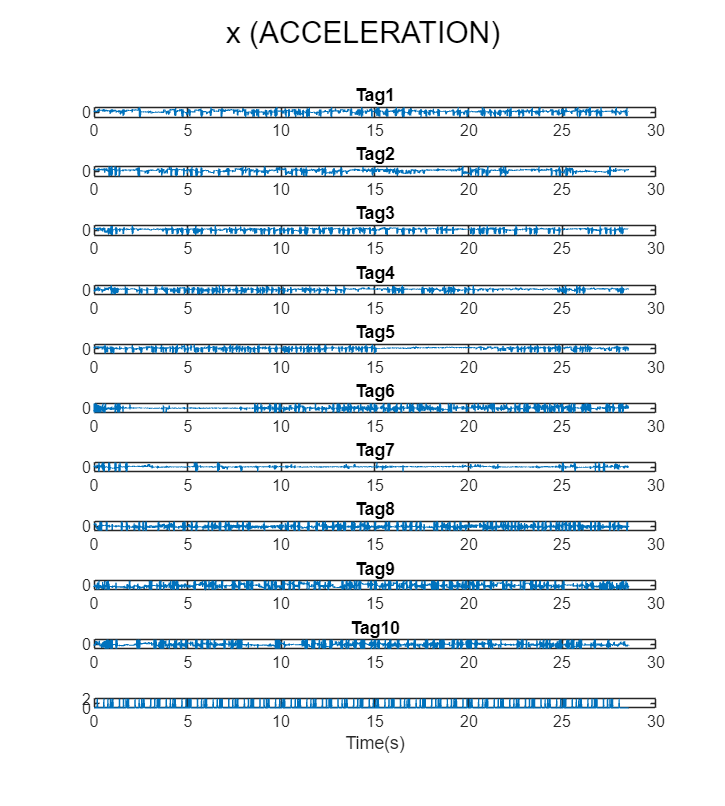

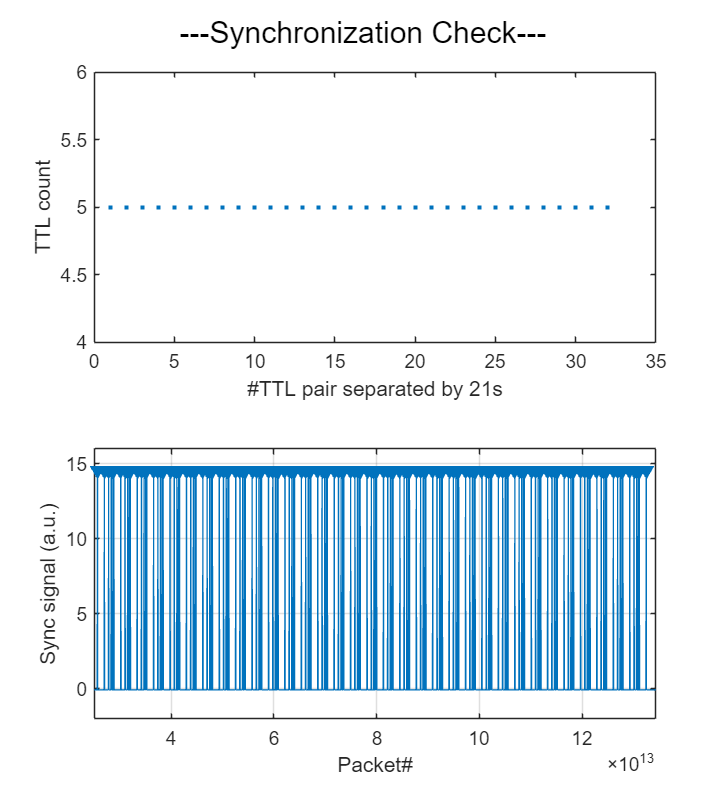

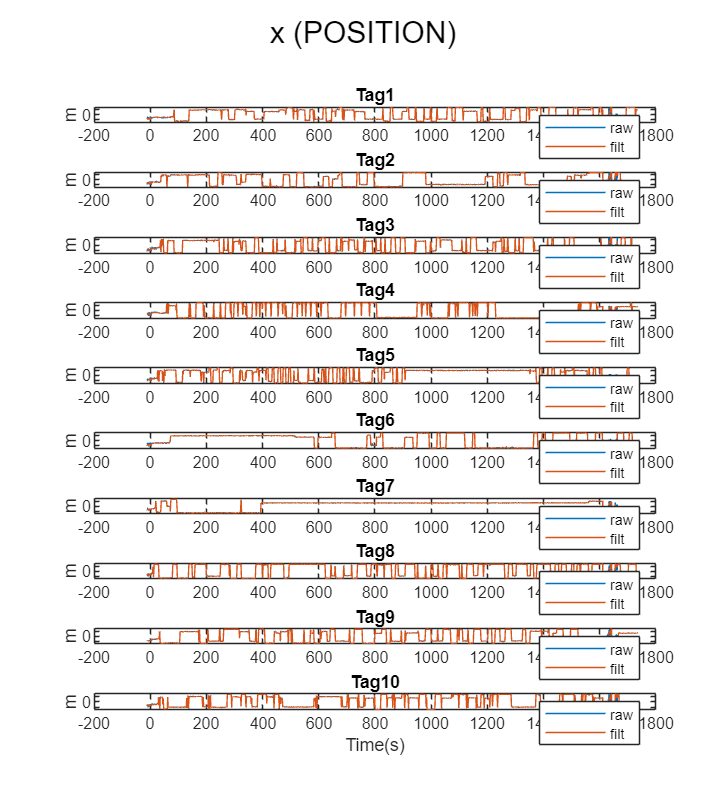

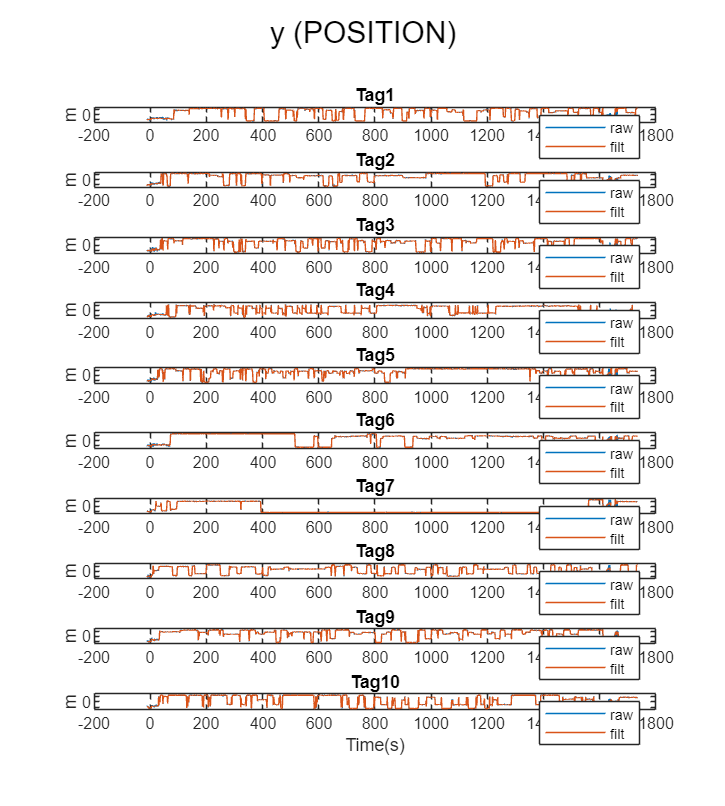

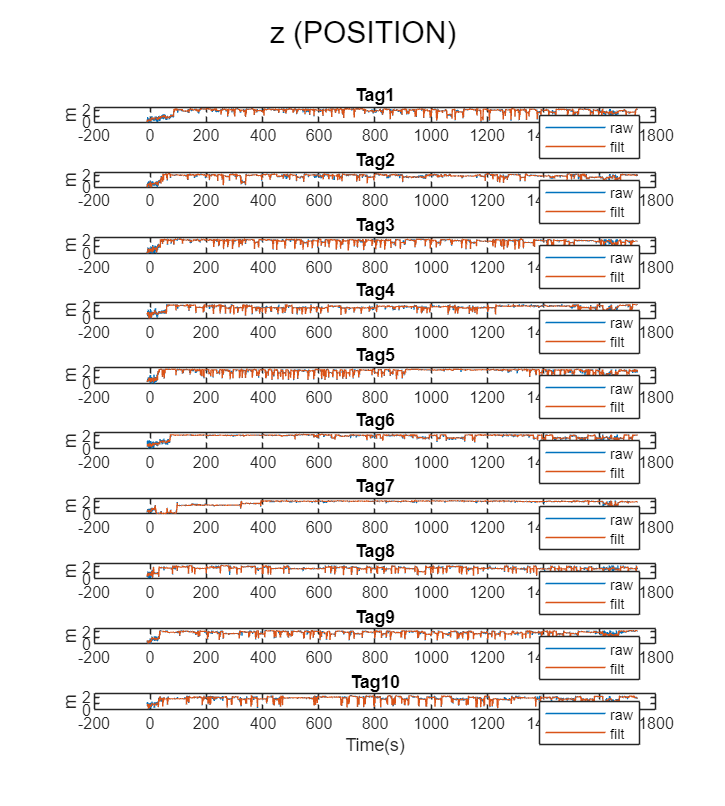

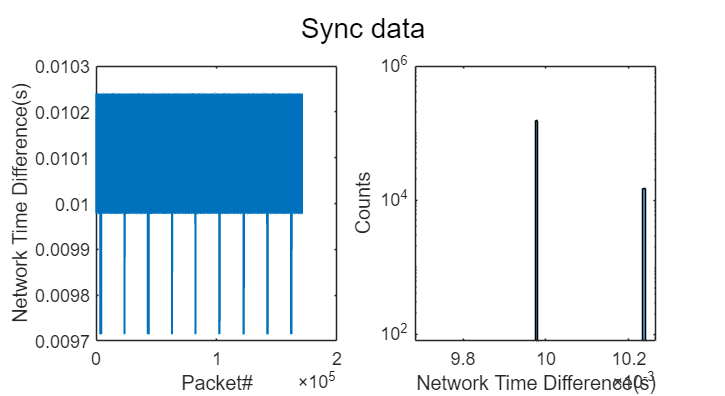

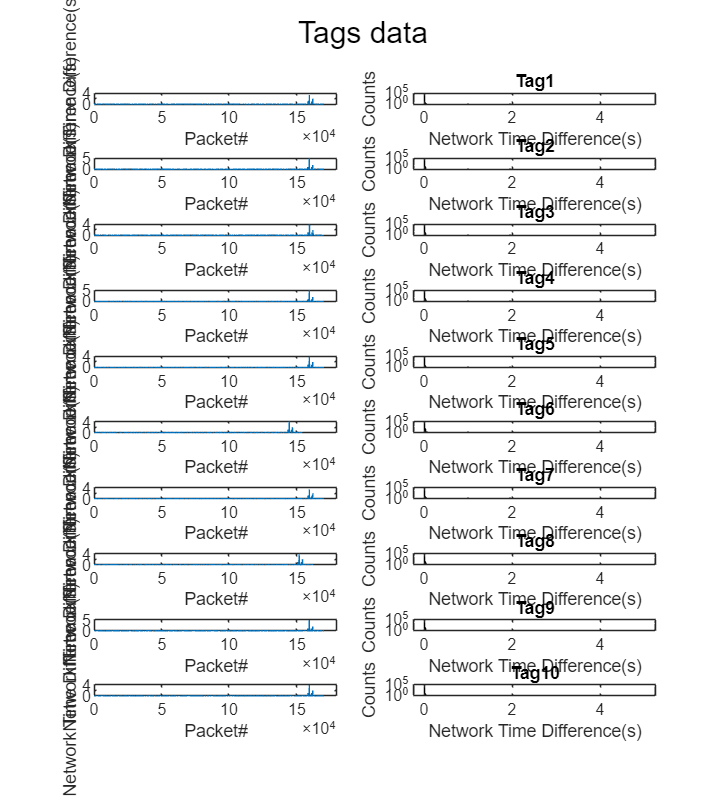

serial_number   =   load(serial_path); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

...Processing Ciholas Data...


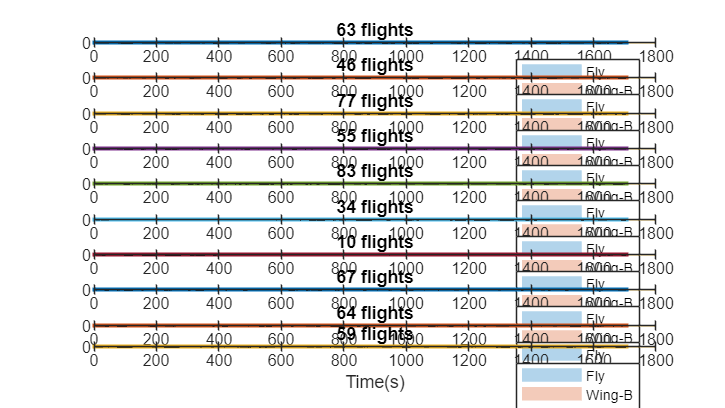

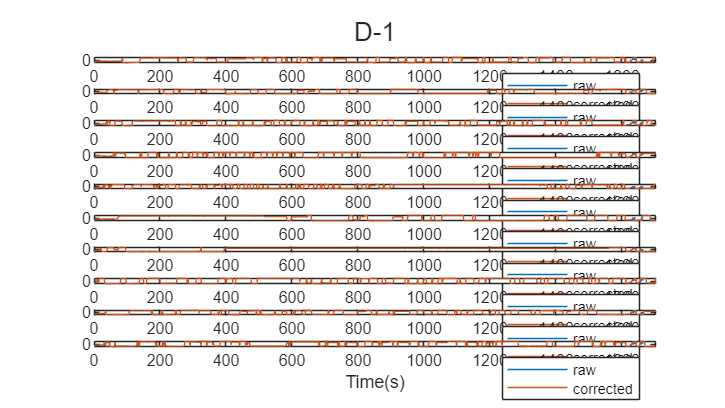

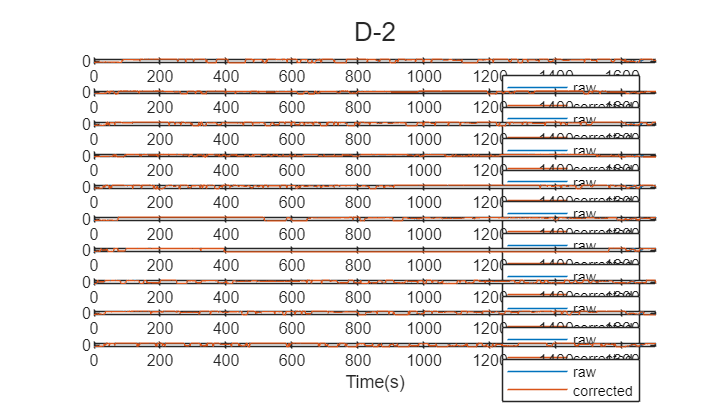

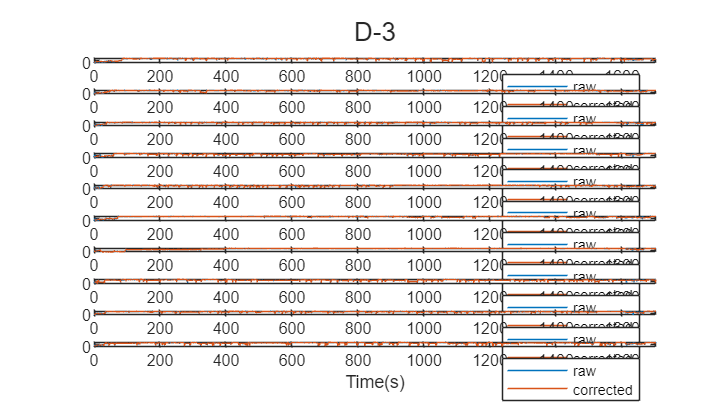

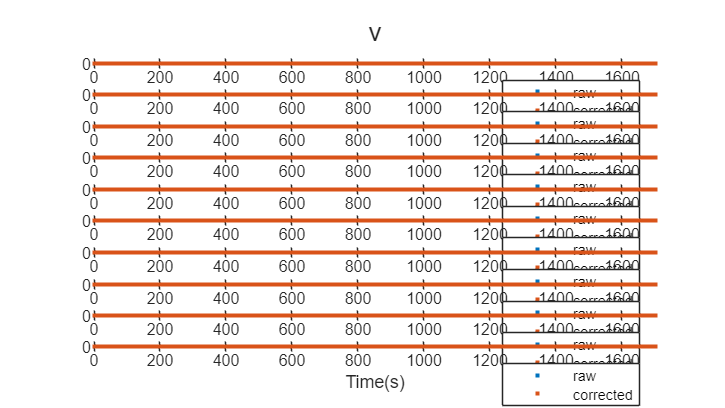

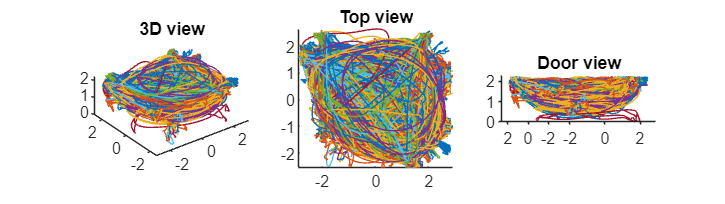

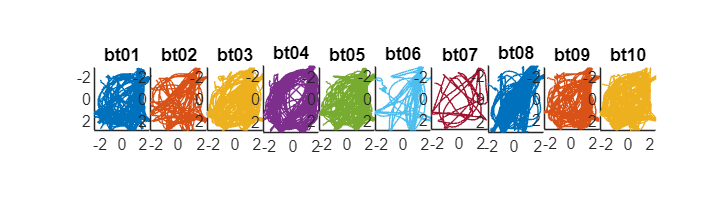

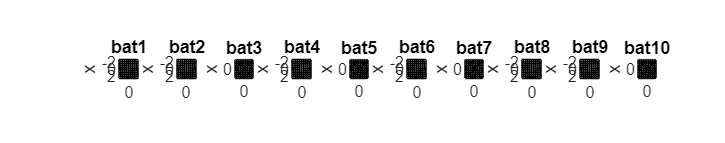

% Extract behaviors
beh_dir             =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(res_dir_path,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end
AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);